# German Stocks - Distributions

## 1.

Load the table stored in the file `daxReturns.mat`.

load daxReturns

## 2.

Use the Distribution Fitting app (`dfittool`) to find a suitable distribution for the index returns (first variable).

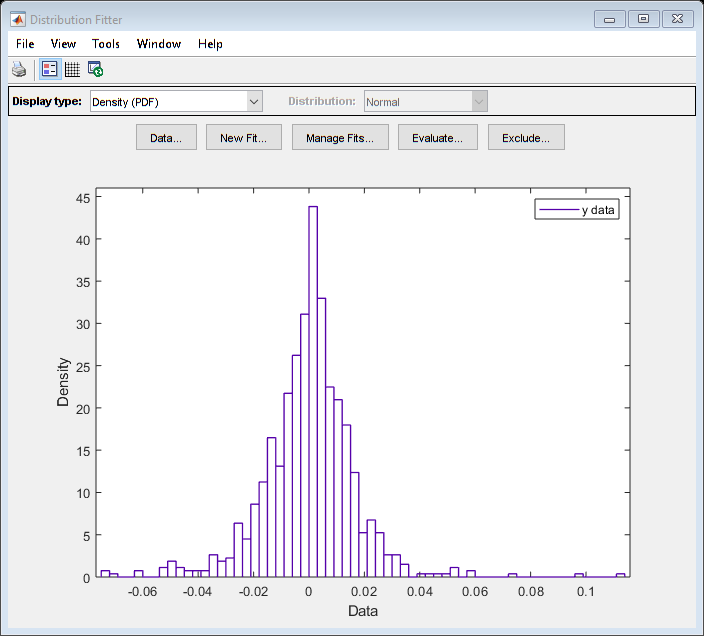

dfittool(daxReturns.DAX)

## 3.

Fit your preferred distribution from step 2 to the data using a command-line function.

daxDist = fitdist(daxReturns.DAX, 'tlocationscale')

daxDist =   tLocationScaleDistribution

  t Location-Scale distribution
       mu = 0.000432699   [-0.000435475, 0.00130087]
    sigma =   0.0108462   [0.00993237, 0.0118441]
       nu =     3.18457   [2.50765, 4.04422]


## 4.

Calculate and display the 1% percentile of the fitted distribution.

disp(['1% percentile: ',num2str(icdf(daxDist,0.01))])

1% percentile: -0.046606


## Bonus

Generate a 25-by-1000 matrix of random values from the fitted return distribution. 

daxRand = random(daxDist,25,1000)

daxRand =     0.0115    0.0063   -0.0070   -0.0038   -0.0079    0.0140   -0.0138   -0.0153    0.0014    0.0081   -0.0053    0.0124   -0.0022   -0.0056    0.0053    0.0007   -0.0043    0.0051   -0.0234   -0.0001    0.0097   -0.0009   -0.0005    0.0010   -0.0072   -0.0325    0.0067   -0.0017    0.0382   -0.0168    0.0144    0.0137   -0.0261   -0.0459   -0.0010    0.0002    0.0017    0.0195    0.0072    0.0200    0.0131    0.0203    0.0157   -0.0035    0.0139    0.0152    0.0091   -0.0007   -0.0067   -0.0044
    0.0156    0.0199    0.0002   -0.0036    0.0037    0.0063   -0.0112   -0.0022    0.0014    0.0042    0.0001    0.0042   -0.0183   -0.0040   -0.0494   -0.0218   -0.0098   -0.0245    0.0125    0.0008   -0.0089    0.0040   -0.0091    0.0074    0.0167   -0.0014   -0.0079    0.0030    0.0048   -0.0063   -0.0081   -0.0114   -0.0186   -0.0120    0.0060    0.0209    0.0116   -0.0176    0.0208   -0.0017   -0.0054    0.0053   -0.0077   -0.0075    0.0007    0.0153    0.0003   -0.0078   -0.045

## Bonus

Transform the random returns into 1000 price series and create a histogram of the final prices.

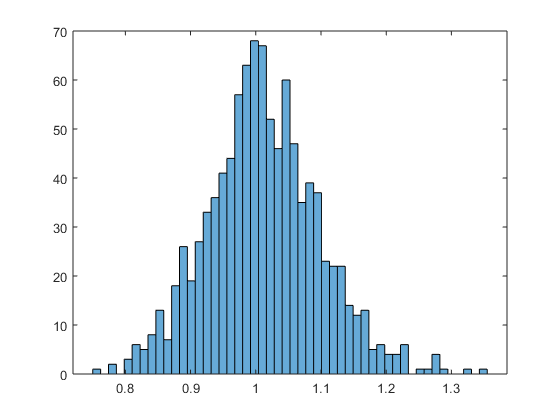

daxRand = exp(cumsum(daxRand));
histogram(daxRand(end,:), 50)